# DSP Online Conference 2024 - 802.11/Wi-fi Channel Estimation

## MATLAB Live Script

September 28, 2024

#### Notation


$$x(n) \\
X(k) \\
h(n)  \Longleftrightarrow  H(k) \\
w(n) \Longleftrightarrow W(k) \\
\hat{h}(n) \\
\hat{H}(k)$$


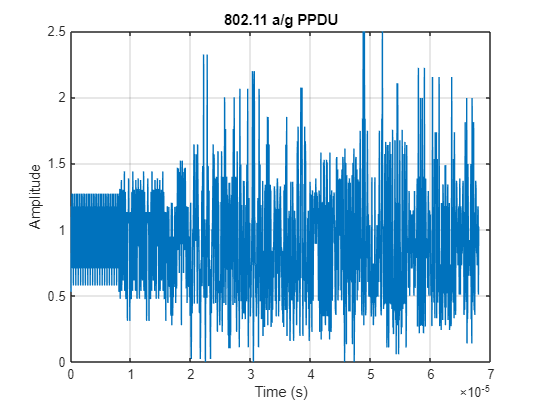

% Setup Random Number Generator
sRng = rng(1, "twister");
% nonHT PPDU
cfgNonHT = wlanNonHTConfig('PSDULength',32);
psdu = randi([0 1],8*cfgNonHT.PSDULength,1,'int8');
y = wlanWaveformGenerator(psdu,cfgNonHT);
figure
fs = 20e6;
td = 1/fs;
lenY = length(y);
t = 0:td:(lenY-1)*td;
plot(t, abs(y))
grid
title ('802.11 a/g PPDU')
xlabel('Time (s)')
ylabel('Amplitude')

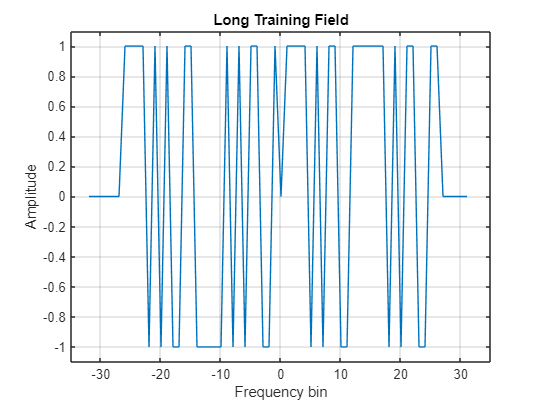

%
% L-LTF
idxLTF = wlanFieldIndices(cfgNonHT,'L-LTF');
ltfFull = y(idxLTF(1):idxLTF(2));
ltfGI = ltfFull(1:32);
ltfSym1 = ltfFull(33:96);
ltfSym2 = ltfFull(97:end);
%
LTF = real(ifftshift(ifft(ltfSym1)));
LTF = LTF / max(LTF);  % Normalize
figure
plot(-32:31,LTF)
axis([-35 35 -1.1 1.1])
grid
title ('Long Training Field')
xlabel('Frequency bin')
ylabel('Amplitude')


$$\hat{H}(k) = \frac{1}{2} 
W(k) [T_1(k) + T_2(k)]$$


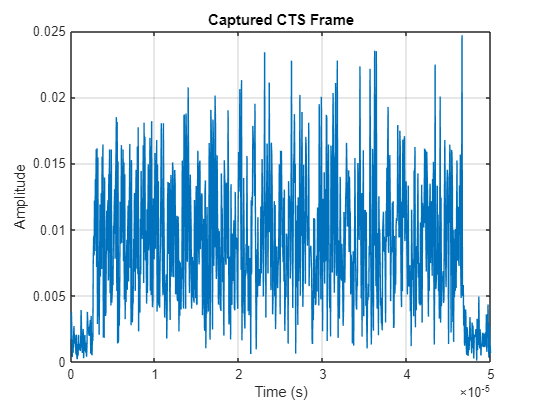

%
% Captured CTS Example
% 80 MHz sampled, repeated on every 20 MHz subchannel
%
load yCTS.mat
nSet = 0:length(yCTS)-1;
fUp = 30.0e6;
fCapture = 80e6;
yCenter = exp(1j*2*pi*fUp/fCapture*nSet) .* yCTS;
fBW = 10e6;
[bFilt, aFilt] = butter(12, fBW/(fCapture/2));
yCenterFiltered = filter(bFilt, aFilt, yCenter);
yCap20 = yCenterFiltered(1:4:end);
ya = yCap20(60:123);
yb = yCap20(124:187);
phaseShift = mean(unwrap(angle(yb) - angle(ya)));
fOffset = fs/64*phaseShift/(2*pi);
nSet2 = 0:length(yCap20)-1;
yCap20 = yCap20 .* exp(-1j*2*pi*fOffset/fs*nSet2);
yCap20 = yCap20.';  % make column vector
lenY = length(yCap20);
SNRdB = 13;
SNR = 10.0^(SNRdB/10.0);
Npower = mean(abs(yCap20).^2) / SNR;
yCap20 = yCap20 + sqrt(Npower/2)*(randn(lenY,1) +1j*randn(lenY,1)); 
figure
t = 0:td:(length(yCap20)-1)*td;
plot(t, abs(yCap20))
grid
title ('Captured CTS Frame')
xlabel('Time (s)')
ylabel('Amplitude')

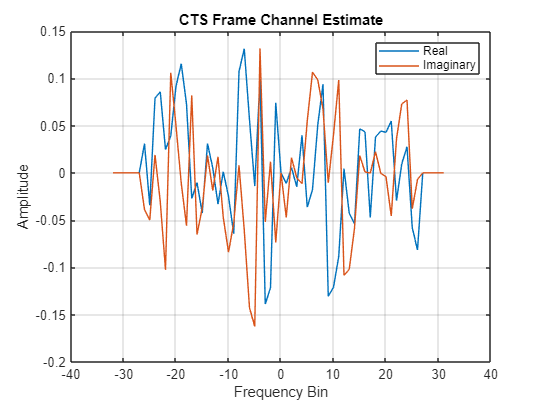

%
%
%startOffset = wlanPacketDetect(yCap20, cfgNonHT.ChannelBandwidth, 1, 0.99) - 5
startOffset = 46;  % Packet detect is not reliable
startLTS = startOffset + 160 + 32;
rLTS1 = fftshift(fft(yCap20(startLTS:startLTS+63)));
rLTS2 = fftshift(fft(yCap20(startLTS+64:startLTS+127)));
%
%
Hest = 0.5*LTF.*(rLTS1+rLTS2);
figure
plot(-32:31,real(Hest),-32:31,imag(Hest))
grid
title ('CTS Frame Channel Estimate')
ylabel('Amplitude')
xlabel('Frequency Bin')
legend ('Real','Imaginary')

%
%
info = wlanNonHTOFDMInfo('NonHT-Data','CBW20');
startData = startLTS + 128+16;
nSyms = floor((length(yCap20) - startData) / 80)

nSyms = 7

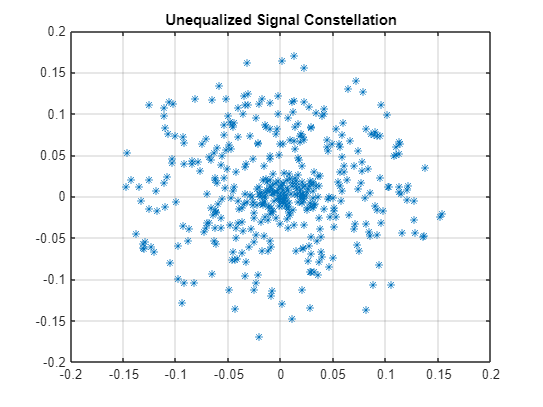

constPts = [];
unEq = [];
G = (Hest(info.ActiveFFTIndices(info.DataIndices)).^-1);
for k = 1:nSyms
  symStart = startData+(k-1)*80;
  symEnd = symStart + 63;
  ySym = yCap20(symStart:symEnd);
  yF = fftshift(fft(ySym));
  unEq = [unEq; yF];
  yFEq = G .* yF(info.ActiveFFTIndices(info.DataIndices));
  constPts = [constPts; yFEq];
end
figure
plot(unEq,'*')
grid
axis([-.2 .2 -.2 .2])
title('Unequalized Signal Constellation')

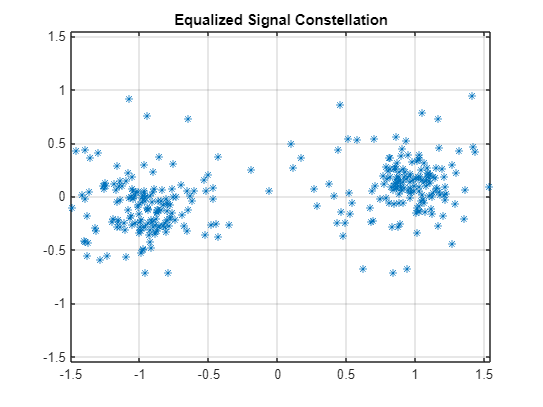

figure
plot(constPts,'*')
grid
axis([-1.5 1.55 -1.55 1.55])
title('Equalized Signal Constellation')

Time Domain Channel Estimation Example


$$y = x_{LTS} \ast h$$



$$X_{LTS} = \left[ \matrix{ l_{15} & l_{14} & l_{13} & ... & l_0 \cr
l_{16} & l_{15} & l_{14} & ... & l_1 \cr
\vdots & \vdots & \vdots & & \vdots \cr
l_{159} & l_{158} & l_{157} & ... & \l_{144} 
} \right]$$



$$y = X_{LTS} \ h$$



$$\hat{h} = u \ s.t.\min_u \| y-X_{lts}u \|^2$$



$$\hat{h} = (X_{LTS}^H \ X_{LTS})^{-1}X_{LTS}^H\ y$$



$$\hat{h} = (X_{LTS}^H \ X_{LTS} + \delta I)^{-1}X_{LTS}^H\ y$$


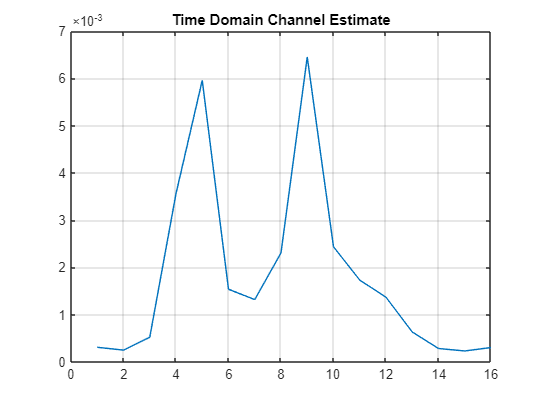

A = toeplitz(ltfFull(16:end), ltfFull(16:-1:1).');
yTr = yCap20(startLTS-17:startLTS+127);
tR = 1.0e-6 * eye(16);
Fest = inv(A'*A +tR)*A';
hEst = Fest*yTr;
figure
plot(abs(hEst))
grid
title ('Time Domain Channel Estimate')

Compare the Channel Estimates

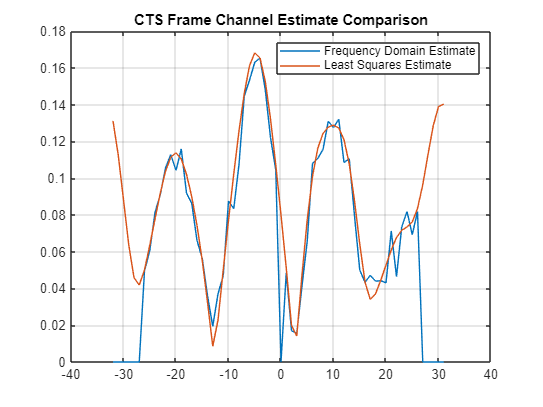

HestTd = fftshift(fft([hEst; zeros(48,1)]));
[maxVal, maxIdx] =  max(abs(Hest));
normF = maxVal / abs(HestTd(maxIdx));
figure
plot(-32:31,abs(Hest),-32:31,normF*abs(HestTd))
legend('Frequency Domain Estimate','Least Squares Estimate')
grid
title ('CTS Frame Channel Estimate Comparison')

Compare the Constellation Plots

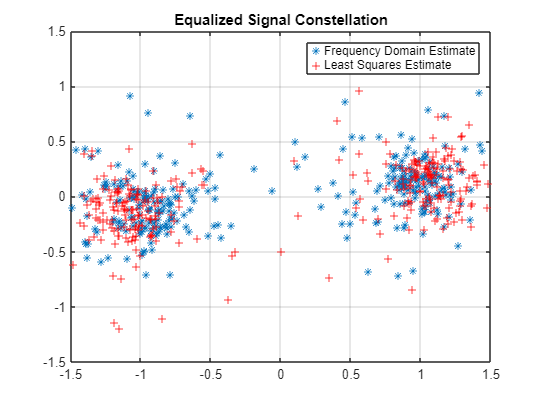

Gtd = (8*HestTd(info.ActiveFFTIndices(info.DataIndices))).^-1;
constPtsTd = [];
for k = 1:nSyms
  symStart = startData+(k-1)*80;
  symEnd = symStart + 63;
  ySym = yCap20(symStart:symEnd);
  yF = fftshift(fft(ySym));
  yFEq = Gtd .* yF(info.ActiveFFTIndices(info.DataIndices));
  constPtsTd = [constPtsTd; yFEq];
end
figure
plot(constPts,'*')
hold on
plot(constPtsTd,'+r')
grid
axis([-1.5 1.5 -1.5 1.5])
legend('Frequency Domain Estimate','Least Squares Estimate')
title('Equalized Signal Constellation')

802.11ax HE-LTF Interpolation

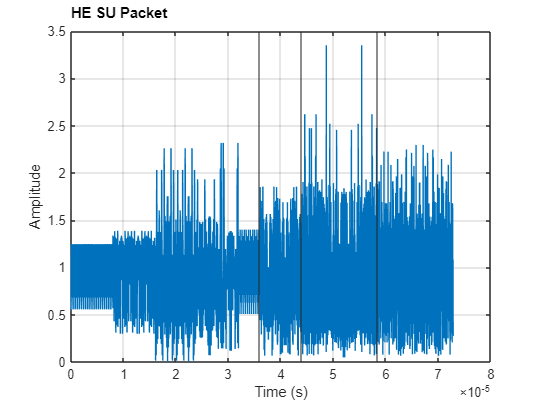

cfgHESU = wlanHESUConfig('ChannelBandwidth','CBW80', 'GuardInterval', 1.6, 'HELTFType', 2);
psduLength = getPSDULength(cfgHESU);
psdu = randi([0 1],8*psduLength,1);
waveformHe = wlanWaveformGenerator(psdu,cfgHESU,'WindowTransitionTime', 0);
figure
ax = gca;
fsHe = 80e6;
tsHe = 1.0/fsHe;
lenHe = length(waveformHe);
t = 0:tsHe:tsHe*(lenHe-1);
plot(t, abs(waveformHe))
title ('HE SU Packet')
set(ax, 'TitleHorizontalAlignment', 'left')
xlabel('Time (s)')
ylabel('Amplitude')
grid
ind = wlanFieldIndices(cfgHESU);
info = wlanHEOFDMInfo('HE-LTF',cfgHESU);
xline(tsHe*double(ind.HELTF(1)-1))
xline(tsHe*double(ind.HELTF(2)-1))
xline(tsHe*double(ind.HELTF(2)-1)+14.4e-6)

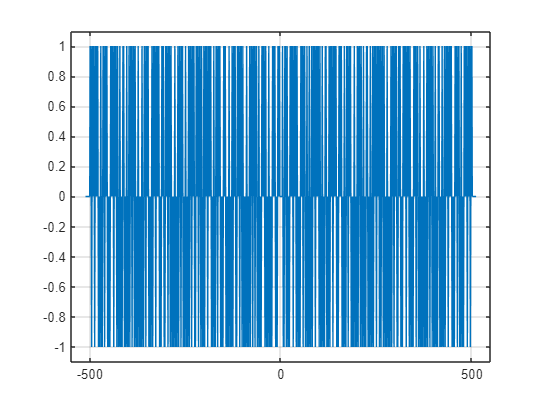

xHeLTFFull = waveformHe(ind.HELTF(1):ind.HELTF(2));
xHeLTF = xHeLTFFull(info.CPLength + 1:end);
xHeLTFfd = fftshift(fft([xHeLTF; xHeLTF]));
xHeLTFfd = 1/max(abs(xHeLTFfd)) * xHeLTFfd;
figure
plot(-512:511, real(xHeLTFfd))
axis([-550 550 -1.1 1.1])
grid

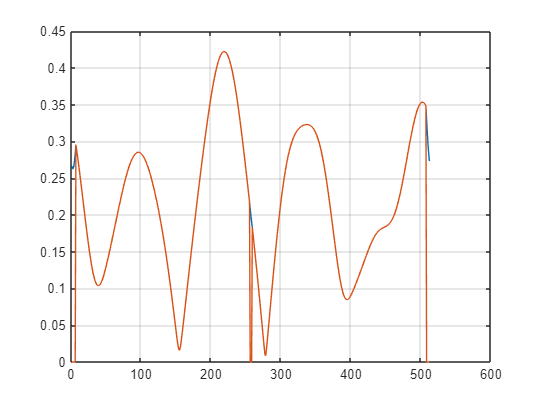

%
% Test with our earlier channel estimate
yOffset = 0;
yRxHe = conv(waveformHe, hEst);
startLTF = yOffset + ind.HELTF(1)+info.CPLength;
stopLTF = startLTF + 512 - 1;
yRxLTF = fftshift(fft(yRxHe(startLTF:stopLTF)));
yRxEst = xHeLTFfd(1:2:end) .* yRxLTF;
yRxEstOrig = yRxEst;
b = yRxEst(255);
m = 1/4*(yRxEst(259) - b);
yRxEst(256:258) = b+m*(1:3);
b = yRxEst(507);
m = 1/12*(yRxEst(7) - b);
yRxEst(1:6) = b*ones(6,1)+m*(6:11).';
yRxEst(508:512) = b*ones(5,1)+m*(1:5).';
figure;
plot(1:512,abs(yRxEst),1:512,abs(yRxEstOrig))
grid

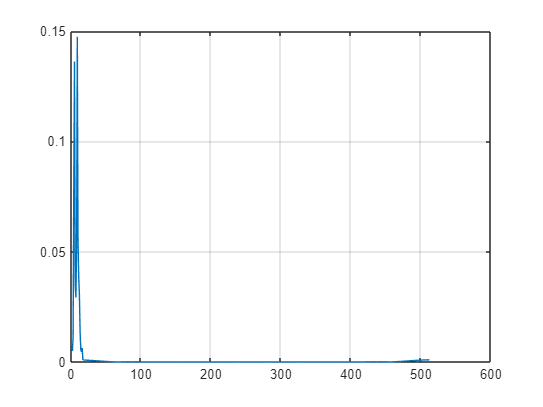

ytDraw = ifft(fftshift(yRxEst));
figure;
plot(abs(ytDraw))
grid

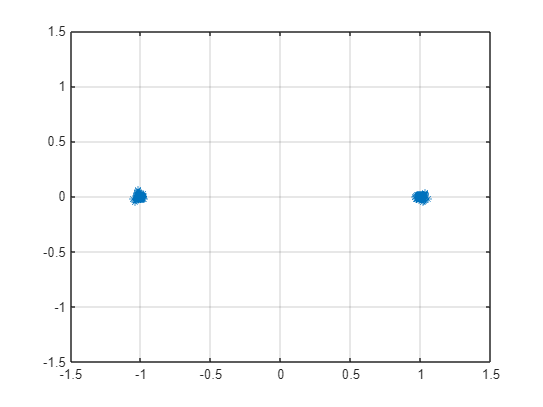

yRxEstFull = sqrt(2.0) * fftshift(fft([ytDraw(1:256); zeros(1024-256,1)]));
%yRxEstFull = zeros(1024,1);
%yRxEstFull(1:2:end) = ytDraw;
%yRxEstFull(2:2:end) = ytDraw;
%
%
startData = yOffset + ind.HEData(1) + info.CPLength;
stopData = startData + 1024 - 1;
yEq = yRxEstFull .^ -1;
ySym = fftshift(fft(yRxHe(startData:stopData)));
ySymEq = ySym .* yEq;
yConstPoints = ySymEq(info.ActiveFFTIndices(info.DataIndices));
figure
plot(yConstPoints,'*')
grid
axis([-1.5 1.5 -1.5 1.5])

MIMO Channel Estimates


$$H(k) = \left[ \matrix{H_{00}(k) & H_{01}(k)  & H_{02}(k) \cr
H_{10}(k) & H_{11}(k) & H_{12}(k) }\right] $$



$$\hat{A}(k) = H_{00}(k) + H_{01}(k) \\
\hat{B}(k) = -H_{00}(k) + H_{01}(k) \\
\hat{C}(k) = H_{10}(k) + H_{10}(k) \\
\hat{D}(k) = -H_{10}(k) + H_{11}(k) \\
$$
